% for proposal and poster
close all
clear all
Obs_wave = 5

Obs_wave = 5

% 创建图窗  
figure;  
h = [];
hi = 0;

% 创建左侧的绘图区域，占图窗的左2/3  
% ax1 = subplot('Position', [0.05, 0.1, 0.6, 0.8]); % [left, bottom, width, height]  

% S_l = load('S_l.txt');
% S_h = load('S_h.txt');
% hi = hi + 1; h(hi) = plot(S_l(1,:), S_l(2,:), "Color", '#033eff', 'LineWidth', 2, 'DisplayName', 'Low albedo model');
% hold on
% hi = hi + 1; h(hi) = plot(S_h(1,:), S_h(2,:), 'Color', '#ff033e', 'LineWidth', 2, 'DisplayName', 'High albedo model');

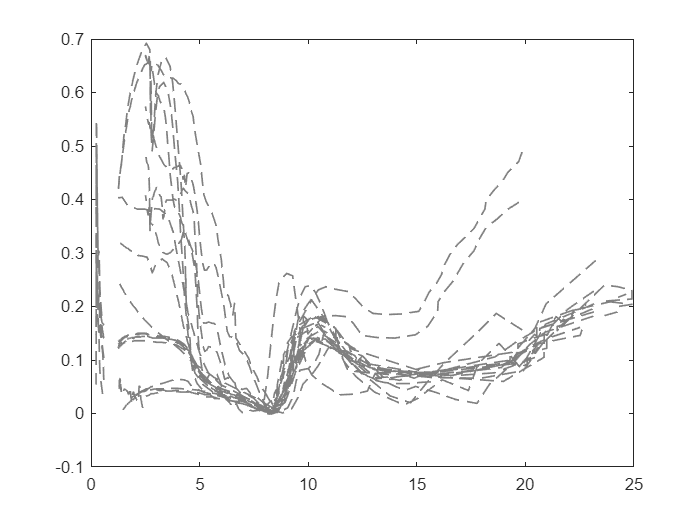


Emit = load('basalt, T=1315 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1) , Emit(:,2), '--', 'DisplayName', 'basalt, 1315 K(Lombardo et al.2020)', 'LineWidth', 1, 'Color','#808080');   % T = 1315 K
% hold off
hold on
j = 0;
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('B-glass, T=1654 K.txt'); % 导入数据
hi = hi + 1; h(hi) = plot(Emit(:,1) , Emit(:,2), '--', 'DisplayName', 'B-glass, 1654 K(Biren et al.2022)', 'LineWidth', 1, 'Color', '#808080');  % T =  1654 K
% 去重
[Emit2(:,1), idx] = unique(Emit(:,1));
Emit2(:,2) = Emit(idx,2);
Emit = Emit2;
clear Emit2
% 保存插值数据
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('B-glass, T=1097 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1) , Emit(:,2), '--', 'DisplayName', 'B-glass, 1097 K(Biren et al.2022)', 'LineWidth', 1, 'Color', '#808080'); % T =  1097 K
[Emit2(:,1), idx] = unique(Emit(:,1));
Emit2(:,2) = Emit(idx,2);
Emit = Emit2;
clear Emit2
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');


Emit = load('B-Nat, T=1648 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1) , Emit(:,2), '--', 'DisplayName', 'B-Nat, 1648 K(Biren et al.2022)', 'LineWidth', 1, 'Color','#808080'); % T =  1648 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('B-Nat, T=1096 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'B-Nat, 1096 K(Biren et al.2022)', 'LineWidth', 1, 'Color','#808080'); % T =  1096 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Fasnia, T=1640 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Fasnia, 1640 K(Biren et al.2022)', 'LineWidth', 1, 'Color','#808080') ; % T =  1640 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load( 'Fasnia, T=1069 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Fasnia, 1069 K(Biren et al.2022)', 'LineWidth', 1, 'Color','#808080'); % T =  1069 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('MORB, T=1653 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'MORB, 1653 K(Biren et al.2022)', 'LineWidth', 1, 'Color','#808080'); % T =  1653 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load( 'MORB, T=861 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName',  'MORB, 861 K(Biren et al.2022)', 'LineWidth', 1, 'Color','#808080'); % T =  861 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('B´arðarbunga basalts, T=1787 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'B´arðarbunga basalts, 1787 K(Howell et al.2020)', 'LineWidth', 1, 'Color', '#808080'); % T =  1787 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Quartz, T=1173 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Quartz, T=1173 K(Thompson et al.2021)', 'LineWidth', 1, 'Color','#808080');   % T =  1173 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Hawaiian basalt, T=1573 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Hawaiian basalt, 1573 K(Thompson et al.2021)', 'LineWidth', 1, 'Color','#808080'); % T =  1573 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');


Emit = load('Hawaiian basalt, T=1073 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Hawaiian basalt, 1073 K(Thompson et al.2021)', 'LineWidth', 1, 'Color','#808080'); % T =  1073 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Forsterite, T=1473 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Forsterite, 1473 K(Thompson et al.2021)', 'LineWidth', 1, 'Color','#808080'); % T =  1473 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Forsterite, T=1073 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Forsterite, 1073 K(Thompson et al.2021)', 'LineWidth', 1, 'Color','#808080'); % T =  1073 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Teide, T=2164 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Teide, 2164 K(Li et al.2022)', 'LineWidth', 1, 'Color','#808080');  % T =  2164 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Teide, T=1187 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Teide, T=1187 K(Li et al.2022)', 'LineWidth', 1, 'Color','#808080');  % T =  1187 K
j = j+1;
[Emit2(:,1), idx] = unique(Emit(:,1));
Emit2(:,2) = Emit(idx,2);
Emit = Emit2;
clear Emit2
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Erebus, T=1608 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Erebus, T=1608 K(Li et al.2022)', 'LineWidth', 1, 'Color','#808080');   % T =  1608 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Erebus, T=1375 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Erebus, T=1375 K(Li et al.2022)', 'LineWidth', 1, 'Color','#808080');   % T =  1375 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('Teide, T=1413 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Teide, T=1413 K(Li et al.2022)', 'LineWidth', 1, 'Color','#808080');   % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');


Emit = load('CaFeSiO F3, T=1627 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '17CaO+40Fe_2O_3+43SiO_2, 1673 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#808080');   % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('CaFeSiO F12, T=1823 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '18.3CaO+43MnO+38.7SiO_2, 1823 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#808080');   % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load('CaFeSiO F4, T=1673 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '21.8CaO+60Fe_2O_3+18.2SiO_2, 1673 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#808080');   % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load( 'CaFeSiO F6, T=1673 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '36CaO+40Fe_2O_3+24SiO_2, 1673 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#808080');   % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load( 'CaFeSiO F7, T=1723 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '40CaO+60Fe_2O_3, 1723 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#808080');   % T = 1723 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load( 'CaFeSiO F10, T=1673 K.txt');
hi = hi + 1; h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '6.5CaO+65.5Fe_2O_3+28P_2O_5, 1673 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#808080');  % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');

Emit = load( 'CaFeSiO F11, T=1823 K.txt');
hi = hi + 1; 
H(4) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', 'Lava samples data', 'LineWidth', 1, 'Color','#808080');  % T = 1413 K

% h(hi) = plot(Emit(:,1), Emit(:,2), '--', 'DisplayName', '28.9CaO+24.1MnO+47SiO_2, 1823 K(Zebger et al.2005)', 'LineWidth', 1, 'Color','#ff8b00');  % T = 1413 K
j = j+1;
Albedo_slice(j) = interp1(Emit(:,1), Emit(:,2), Obs_wave,'linear');


lam = [0.59772863 0.60435266 0.61097669 0.61760072 0.62422475 0.63084878 ...
 0.63747281 0.64409684 0.65072087 0.6573449  0.66396893 0.67059296 ...
 0.67721699 0.68384102 0.69046505 0.69708909 0.70371312 0.71033715 ...
 0.71696118 0.72358521 0.73020924 0.73683327 0.7434573  0.75008133 ...
 0.75670536 0.76332939 0.76995342 0.77657745 0.78320148 0.78982551 ...
 0.79644954 0.80307357 0.8096976  0.81632163 0.82294566 0.82956969 ...
 0.83619372 0.84281775 0.84944178 0.85606581 0.86268984 0.86931387 ...
 0.8759379  0.88256193 0.88918596 0.89580999 0.90243402 0.90905805 ...
 0.91568208 0.92230611 0.92893014 0.93555417 0.94217821 0.94880224 ...
 0.95542627 0.9620503  0.96867433 0.97529836 0.98192239 0.98854642 ...
 0.99517045 1.00179448 1.00841851 1.01504254 1.02166657 1.0282906 ...
 1.03491463 1.04153866 1.04816269 1.05478672 1.06141075 1.06803478 ...
 1.07465881 1.08128284 1.08790687 1.0945309  1.10115493 1.10777896 ...
 1.11440299 1.12102702 1.12765105 1.13427508 1.14089911 1.14752314 ...
 1.15414717 1.1607712  1.16739523 1.17401926 1.18064329 1.18726733 ...
 1.19389136 1.20051539 1.20713942 1.21376345 1.22038748 1.22701151 ...
 1.23363554 1.24025957 1.2468836  1.25350763];

R = [0.14012    0.13959189 0.1390782  0.13857873 0.13809327 0.13762162 ...
 0.13716358 0.13671894 0.13628751 0.13586908 0.13546345 0.13507042 ...
 0.13468977 0.13432132 0.13396485 0.13362017 0.13328708 0.13296536 ...
 0.13265482 0.13235525 0.13206645 0.13178823 0.13152036 0.13126267 ...
 0.13101493 0.13077695 0.13054853 0.13032946 0.13011955 0.12991858 ...
 0.12972635 0.12954267 0.12936733 0.12920012 0.12904085 0.12888931 ...
 0.1287453  0.12860862 0.12847906 0.12835642 0.1282405  0.1281311 ...
 0.12802801 0.12793103 0.12783996 0.12775459 0.12767473 0.12760017 ...
 0.1275307  0.12746613 0.12740625 0.12735086 0.12729976 0.12725274 ...
 0.12720961 0.12717015 0.12713417 0.12710146 0.12707183 0.12704506 ...
 0.12702096 0.12699932 0.12697994 0.12696262 0.12694715 0.12693334 ...
 0.12692098 0.12690986 0.12689979 0.12689056 0.12688197 0.12687382 ...
 0.1268659  0.12685801 0.12684995 0.12684151 0.1268325  0.12682271 ...
 0.12681194 0.12679998 0.12678664 0.1267717  0.12675498 0.12673626 ...
 0.12671534 0.12669202 0.12666609 0.12663736 0.12660563 0.12657068 ...
 0.12653232 0.12649034 0.12644454 0.12639472 0.12634068 0.12628221 ...
 0.12621911 0.12615117 0.12607821 0.126     ];

% hi = hi + 1; h(hi) = plot(lam, R, '-','LineWidth', 1, 'DisplayName','interpolation') 


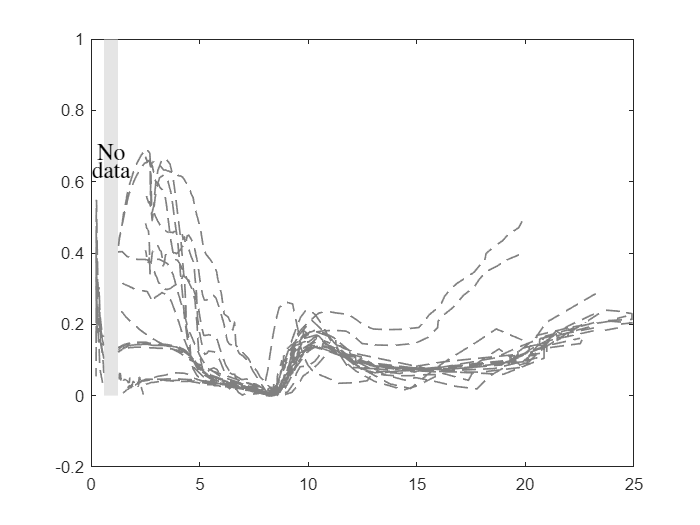

% 定义带状区域的 x 坐标和对应的 y 坐标  
x_fill = [0.6, 1.243, 1.243, 0.6];  
y_fill = [0, 0, 1, 1]; % 适合于此数据范围内的 y 坐标极值  

% 使用 patch 函数填充背景色为灰色  
patch(x_fill, y_fill, [0.8 0.8 0.8], 'EdgeColor', 'none', 'FaceAlpha', 0.5);  
text((x_fill(1)+x_fill(2))/2, 0.68, 'No', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle','Interpreter', 'Latex', 'FontSize', 14)
text((x_fill(1)+x_fill(2))/2, 0.63, 'data', 'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle','Interpreter', 'Latex', 'FontSize', 14)

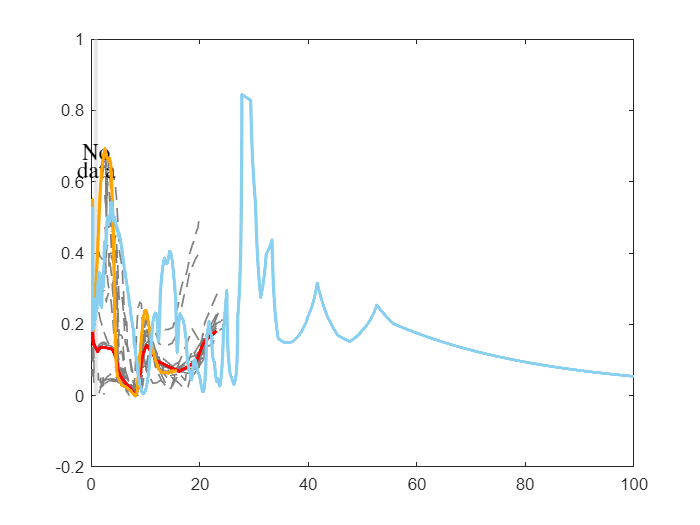

S_l = load('S_l.txt');
S_h = load('S_h.txt');
Solid_Al2O3 = readtable('Al2O3_spher_albedo.txt', 'HeaderLines', 1); 
Solid_Al2O3 = table2array(Solid_Al2O3);
% Solid_Al2O3 = load('Al2O3_spher_albedo.txt');
% Solid_Al2O3_2 = load("solid_Al2O3_o2.txt");
% Solid_Al2O3_3 = load("film_Al2O3.txt");

% n_Al2O3 = Solid_Al2O3(:,2);
% k_Al2O3 = Solid_Al2O3(:,3);
% R_Al2O3 = ((n_Al2O3 - 1).^2 + k_Al2O3.^2)./((n_Al2O3 + 1).^2 + k_Al2O3.^2);
R_Al2O3 = Solid_Al2O3(:,2);

% n_Al2O3_2 = Solid_Al2O3_2(:,2);
% R_Al2O3_2 =  ((n_Al2O3_2 - 1).^2)./((n_Al2O3_2 + 1).^2 );
% n_Al2O3_3 = Solid_Al2O3_3(:,2);
% k_Al2O3_3 = Solid_Al2O3_3(:,3);
% R_Al2O3_3 = ((n_Al2O3_3 - 1).^2 + k_Al2O3_3.^2)./((n_Al2O3_3 + 1).^2 + k_Al2O3_3.^2);

H(1) = plot(S_l(1,:), S_l(2,:), "Color", '#FF0000', 'LineWidth', 2, 'DisplayName', 'Low albedo model');
hold on
H(2) = plot(S_h(1,:), S_h(2,:), 'Color', '#FFA500', 'LineWidth', 2, 'DisplayName', 'High albedo model');
% H(3) = plot(SSA(:,1), SSA(:,2), 'Color', '#89cff0', 'LineWidth', 2, 'DisplayName', 'Al_2O_3 SSA');
H(3) = plot(Solid_Al2O3(:,1), R_Al2O3, 'Color', '#89cff0', 'LineWidth', 2, 'DisplayName', 'Solid Al_2O_3');

% H(4) = plot(Solid_Al2O3_3(:,1), R_Al2O3_3,'color', 'k', 'LineWidth', 2, 'DisplayName', 'Solid Al_2O_3 Malitson et al. 1972');

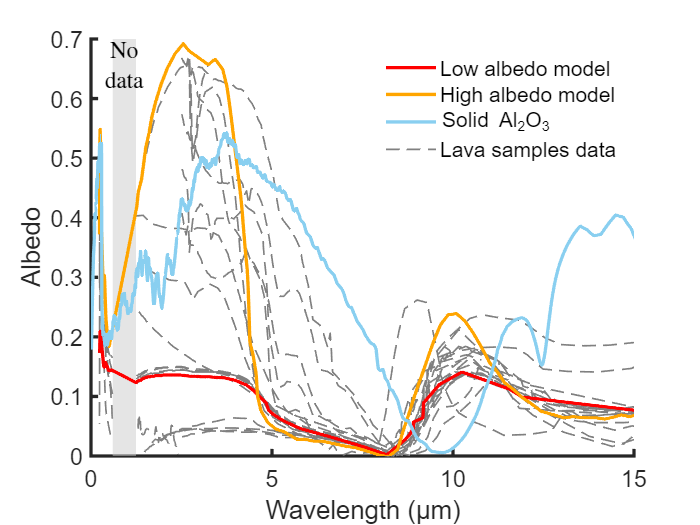


xlabel('Wavelength (μm)')
ylabel('Albedo')
axis([0,15,0,0.7])
% uistack(h(1), 'top')
lgd = legend(H);
lgd.Color = 'none';
legend boxoff

ax1 = gca;
% 创建右侧的图例区域，占图窗的右1/3  
% ax2 = subplot('Position', [0.7, 0.1, 0.25, 0.8]); % [left, bottom, width, height]  
% axis(ax2, 'off'); % 隐藏坐标轴  
% legend(ax2, H ,'Location', 'northwest')
% 调整布局  
set(ax1, 'Box', 'off'); % 移除box线条  
% 设置坐标轴的线宽  
ax1.LineWidth = 2; % 设置线宽为2  

% 设置坐标轴的字号  
ax1.FontSize = 14; % 设置字号为14 

% colormap('jet')
% cb = colorbar;
% % 设置颜色轴的范围  
% caxis([861, 2164]); % 设置 colorbar 的最小值和最大值  
% 
% % 设置 colorbar 的标签  
% cb.Label.String = 'Temperature (K)'; 
% cb.Label.FontSize = 12;  
% cb.Label.FontName = 'Arial'; 

function P = planck_func(T, lam, B)
    if nargin < 3
        B = 1;
    end
    h = 6.626e-34 ;
    c = 3.0e8 ;
    k = 1.38e-23;  
    P = 2* B * h * c^2 ./ lam.^5 ./ (exp(h * c ./ lam ./ k ./ T) - 1);
end

function P = P_cal(T_h, T_c, A_h, lam)
    P = A_h/100 * planck_func(T_h + 273, lam) + (1-A_h/100) * planck_func(T_c+273, lam);
    P = P*1e-8;
end
    
